% MANUALLY LOAD .mat FILES FOR INDIVIDUAL ANALYSIS

% CALC'S FOR LATER
RoundXpts = round(abs(ypts)); %switch x & y
RoundYpts = round(abs(xpts));


clear PTSdfof % pulling fluoresence data from just teh points picked in threshPassAnalysis script
for i = 1:length(xpts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end
display('size of PTSdfof is: ')
size(PTSdfof)


% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
uniqueContrasts = unique(con); % for looping over contrast values later


% DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); % save in new vector that is a list 
% of trial conditions ordered by trial

uniqueDurations = unique(dur); % for looping later


% common figure calc's

reigons = {'V1','LM','RL','PM','control'};
cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
durs4Legend = {'16','33','66','133','266'};


% DURATION FIGURES

% 1st fig on Group Contrast is independant of Con vs Dur... not repeating it here

% MEAN DF/F vs FRAMES for each DURATION, per visual area
% mean TRACE = duration, SUBPLOT = point

clear subplotNum
subplotNum = 1;
clear r
r = 1;

figure % only making 1 figure
suptitle(sprintf('df/f vs frames for each duration in each visual area'))   

clear i
for i = 1:length(xpts) % for each point
    subplot(2,3,i) % give each point it's own subplot
    % on each subplot plot the mean dfof across trials, vs frames
    
    % now on each subplot/for each point we're going 
    % to plot the mean across trials at each contrast, for each contrast
    clear d
    for d = 1:length(uniqueDurations) 
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
        
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % creating a 
        % 1x51 variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frames
        
        %STDEV
        clear err
        err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
        % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
        % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
        
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
        
        errorbar(frameNum,meanOverTrialsPTSdfof,err,'linewidth',1)
        ylim([-0.02 0.05]) 
        xlim([0 51])
        st = title(sprintf('%s', reigons{r}));

        
        if subplotNum == 1
            ylabel('df/f')
            xlabel ('frames')
        else
            set(gca,'XTick',[], 'YTick', [])
        end
        
        hold on
       
    end
    
    if subplotNum == 1
        legend(durs4Legend)
    end
    
    subplotNum = subplotNum + 1;
    r = r+1;
    
end 
    
    % collect all the matricies for all the i-th points
%     sqForGroupMeanOverTrialsPTSdfof = squeeze(forGroupMeanOverTrialsPTSdfof);
%     allPtsMeanOverTrialsPTSdfof(:,:,i) = sqForGroupMeanOverTrialsPTSdfof;
    
% now for each contrast figure, I want the 6th subplot to be the
% average trace for each contrast, across visual areas
    
hold on

clear d
for d = 1:length(uniqueDurations)
    
    subplot(2,3,6) 
        
    clear dthTrials
    dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
    dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
       
    clear allIthDthMeanSqPTSdfofDthTrials % this gets cleared out in between contrasts, not points
        
    clear i
    for i = 1:length(xpts) 
            
        % collect mean df/f vs frames for each point at the c-th contrast
        allPtsAtDthDurMeanSqPTSdfofDthTrials(i,:) = mean(squeeze(PTSdfof(i,:,dthTrials)),2)';
    
    end
    
    clear meanOverPts4DthConMeanSqPTSdfofDthTrials
    
    % take the mean across points of the matrix we just collected
    % this gives us one trace for all points at the cth contrast
    meanOverPts4DthDurMeanSqPTSdfofDthTrials = mean(allPtsAtDthDurMeanSqPTSdfofDthTrials,1);
    
    plot(meanOverPts4DthDurMeanSqPTSdfofDthTrials,'linewidth',2) 
       
    hold on

end
    
ylim([-0.02 0.05])
xlim([0 51])
sst = title('mean per duration')

sst =   Text (mean per duration) with properties:

                 String: 'mean per duration'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [25.5 0.050716 1.4211e-14]
                  Units: 'data'

  Show all properties


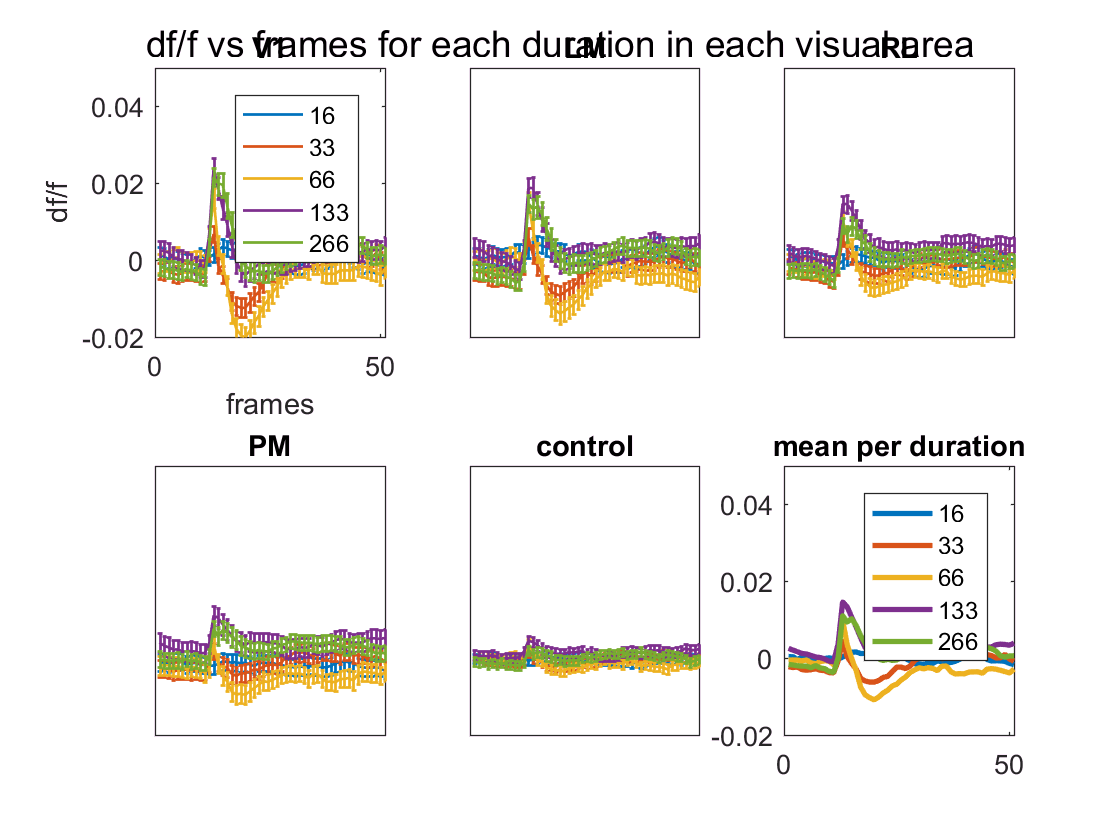

legend(durs4Legend)

% LATENCY vs DURATION for each Vis Area
% find the max, and then the frame the max is at

% lets pick 
clear d
clear i

% 7 contrasts for x axis
clear x_xis
x_axis = [1 2 3 4 5];

subplotNum = 1

subplotNum =      1


r = 1

r =      1


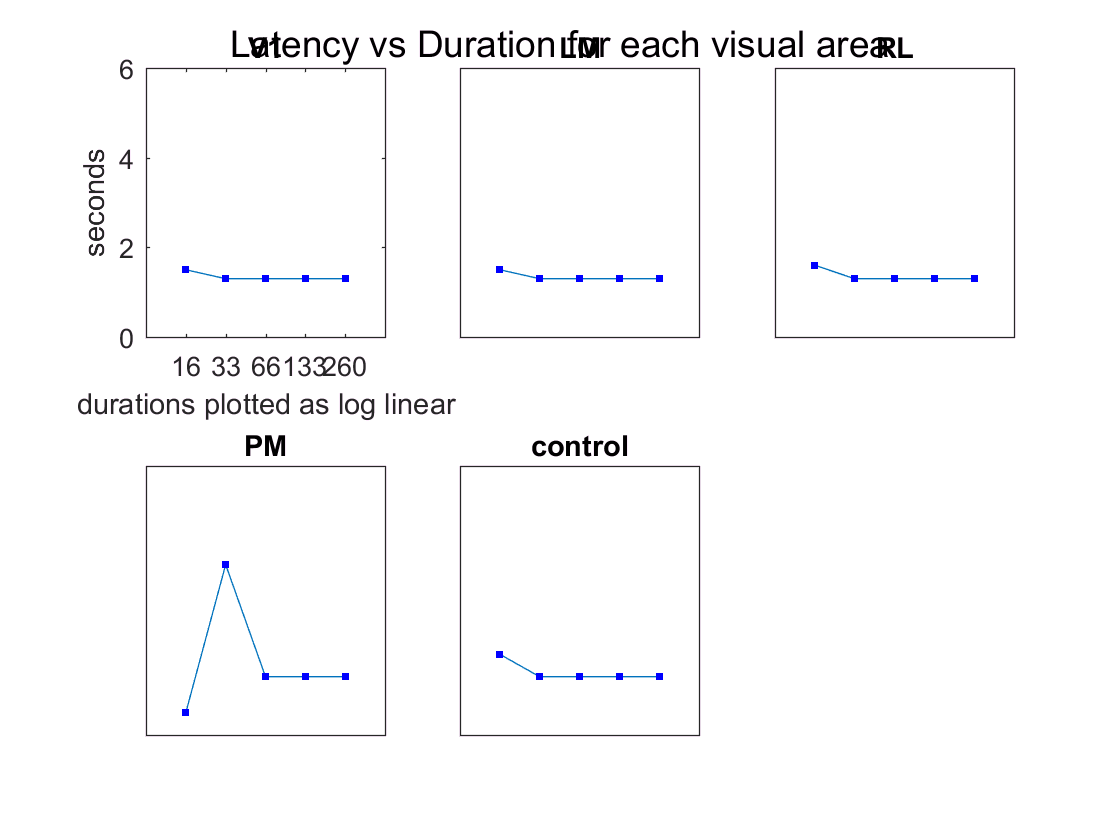


figure;
suptitle('Latency vs Duration for each visual area')
for i = 1:length(xpts)
    
    clear maxDurRespOverFramesTrialsPTSdfof % clear this so the mean dfof for each points dont write over each other, plotting nonsense
    clear durLatencyInFrames
    
    for d = 1:length(uniqueDurations)
        
        clear meanOverTrialsPTSdfof
        clear maxOverFramesTrialsPTSdfof 
        clear latencyInFrames
        clear dthTrials
        
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
        
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        maxOverFramesTrialsPTSdfof = max(meanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        latencyInFrames = find(meanOverTrialsPTSdfof == maxOverFramesTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        durLatencyInFrames(1,d) = latencyInFrames; % one row, each 7 columnns  
        
        % saving each cth latency value 
        durMaxOverFramesTrialsPTSdfof(1,d) = maxOverFramesTrialsPTSdfof;
        
        % STDEV
        % we only want the frames for the latencies for our max values, but still need stdev over trials
        %latTrials = latencyInFrames
        stdErrDurLatOverTrials(1,d) = std(PTSdfof(i,latencyInFrames,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    clear convertFrames2Sec
    convertFrames2Sec = 0.1*durLatencyInFrames;
    
    % for GROUP
    % collect all the latency for each contrast over all trials into a 2-D variable
    % with the cells as latency, 1st dimension as points (rows), the second dim as contrasts
    % the below is 5 x 7 
     %allPtsConvertFrames2Sec(i,:) = convertFrames2Sec;
     
    % still w/in the points for loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     % scatter(x_axis,convertFrames2Sec)
     errorbar(x_axis,convertFrames2Sec,stdErrDurLatOverTrials,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     st = title(sprintf('%s', reigons{r}));
     ylim([0 6]) 
     xlim([0 6])
     
     if subplotNum == 1
        xlabel('durations plotted as log linear')
        ylabel('seconds')
        xt={'16' ; '33' ; '66' ; '133' ; '260';} ; 
        set(gca,'xtick',1:5);
        set(gca,'xticklabel',xt);
    else
        set(gca,'XTick',[], 'YTick', [])
    end
    
subplotNum = subplotNum + 1;
r = r + 1;
     
end

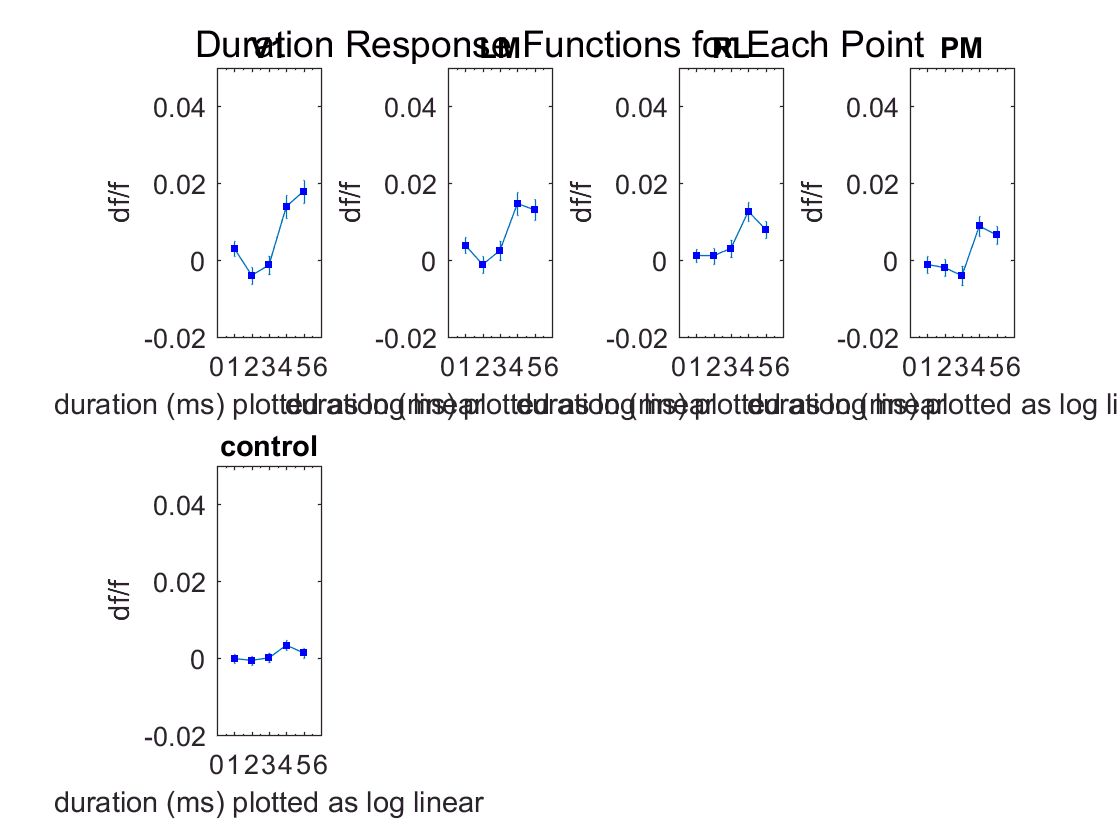

% DRF w/ PEAK (MEAN @ LATENCY) --> determined by looking at latency.. just taking mean at these frames, not using max function
% DRF over frames 14-16

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;

subplotNum = 1;
r = 1;

figure 
suptitle('Duration Response Functions for Each Point')
for i = 1:length(xpts)
    
    clear sq5FramesOverTrialsPTSdfof
    clear meanOverFramesSq5FramesOverTrialsPTSdfof
    clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear durStdErr
    
    for d = 1:length(uniqueDurations)
        
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
        
        % DRF POINTS for each contrast, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,dthTrials));
        
        % take the mean over frames
        %returns 1 x 76 (trials)
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each d-th DRF value for this point
        % creates 1 x 5 (duratoins)
        durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr;
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that point
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5];
    drfChart = errorbar(x_axis,durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,durStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    st = title(sprintf('%s', reigons{r}));
    ylim([-0.02 0.05]) 
    xlim([0, 6])
    ylabel('df/f')
    xlabel('duration (ms) plotted as log linear')
    
    ax=drfChart.Parent;
    ax.XMinorTick = 'on'; %more tick marks
    set(ax, 'XTick', 0:1:6);
%     clear xt
%     xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
%     set(gca,'xtick',1:7);
%     set(gca,'xticklabel',xt);
    
subplotNum = subplotNum+1;
r = r+1;
    
end 


%savefig('G6H277RT_020421_CRF_imThreshPass')

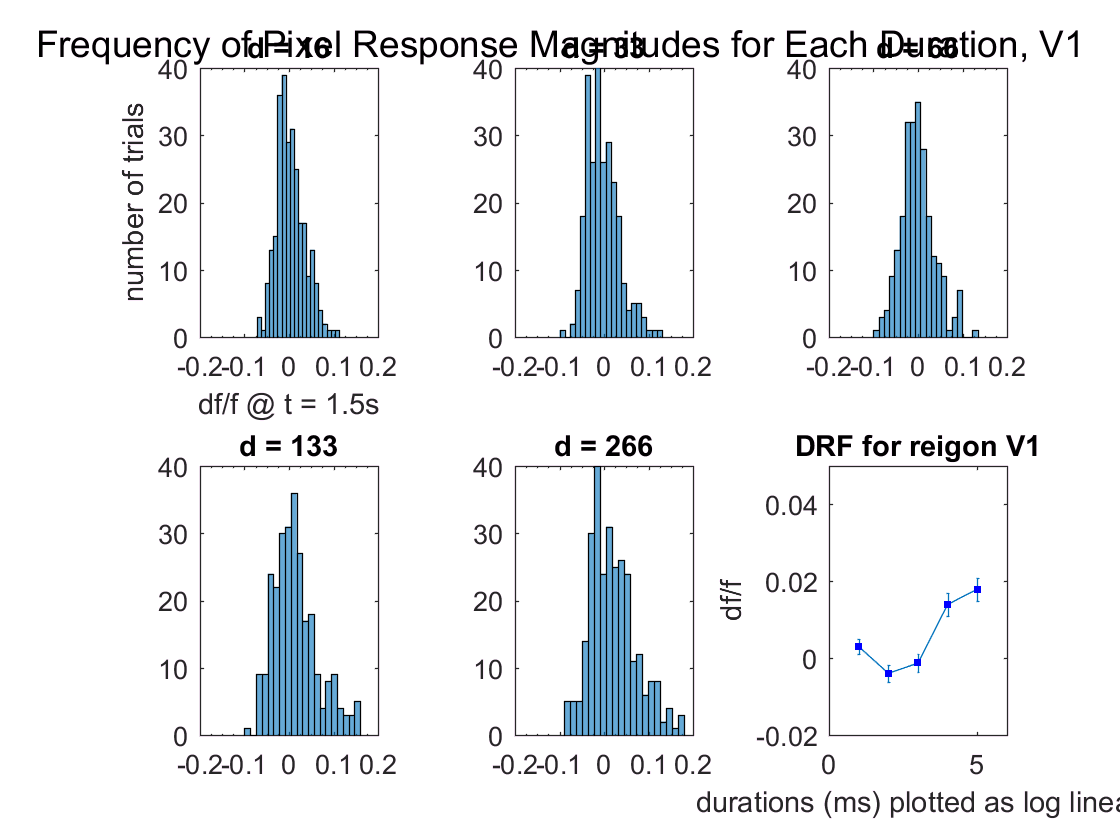

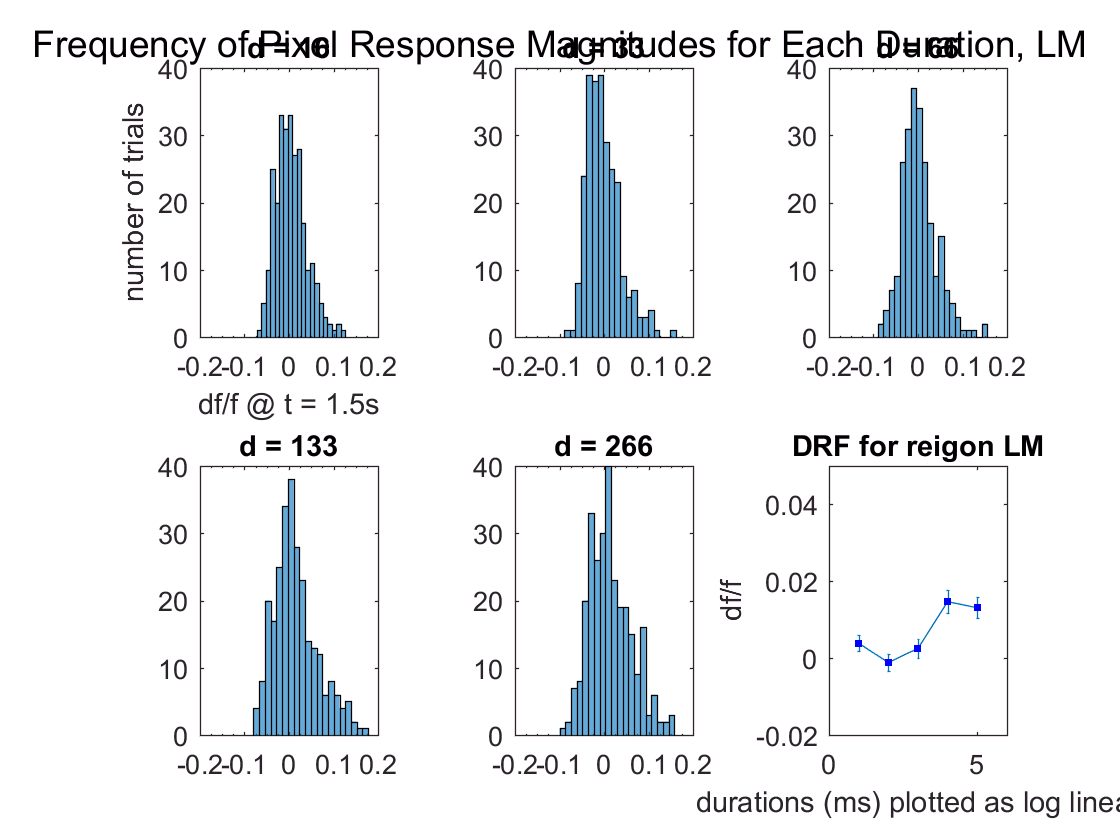

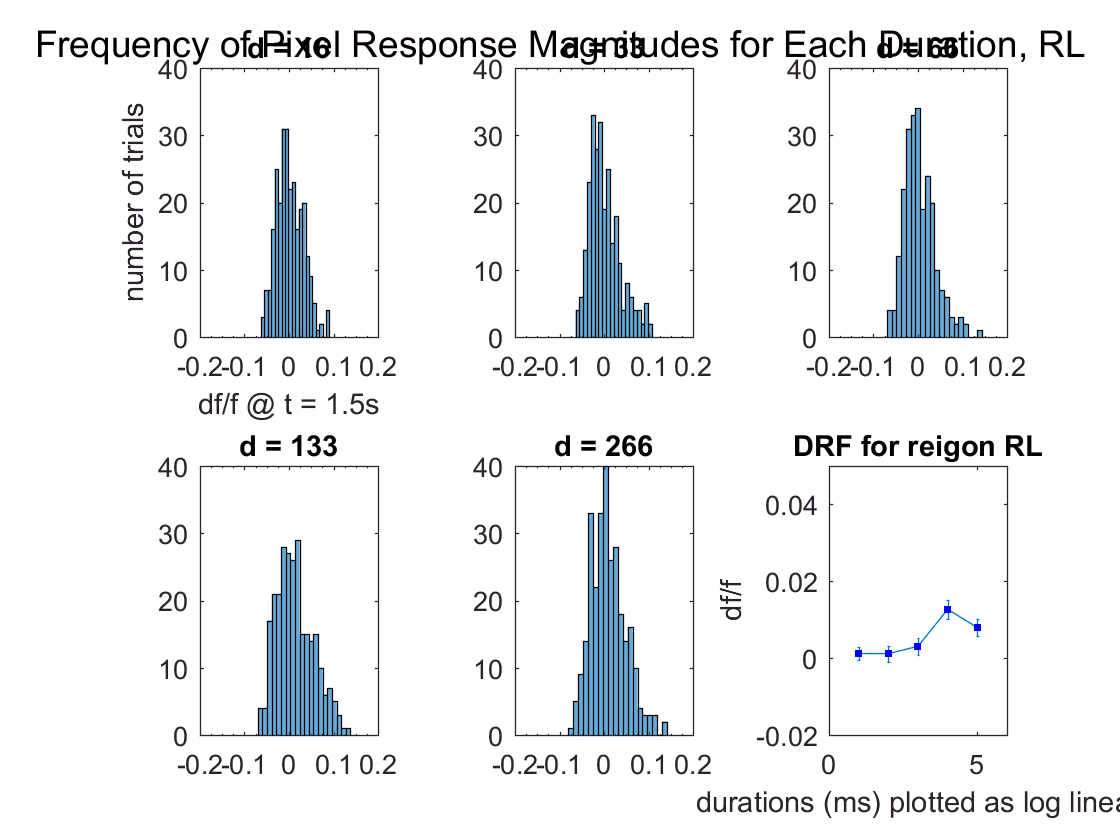

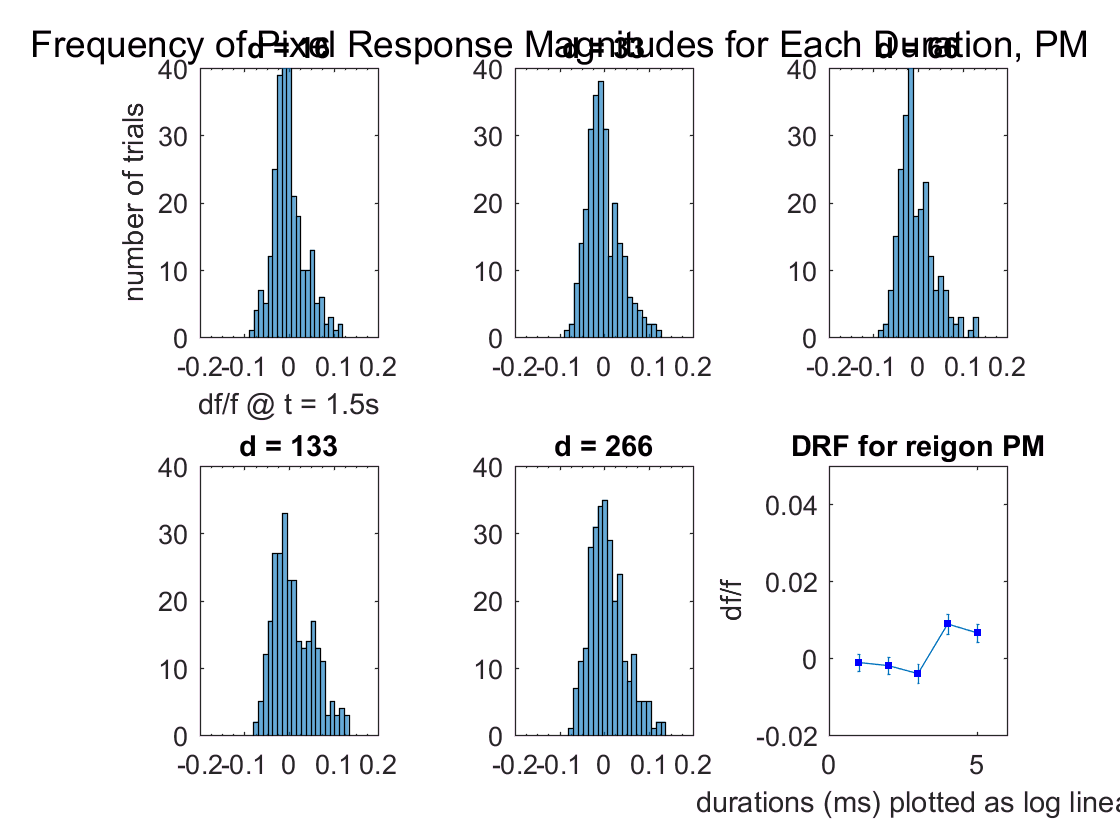

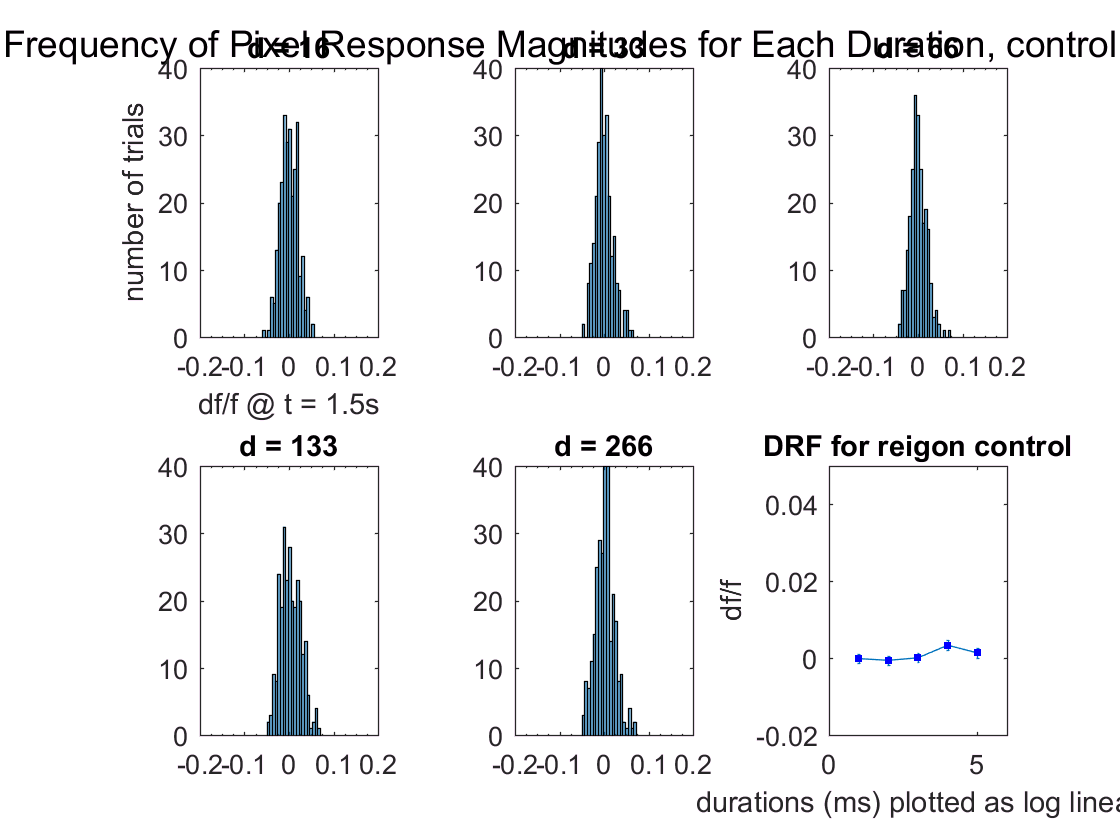

% DISTRIBUTION
% Now need to plot the distribution of amplitude values at t = 15, for each contrast and each point

clear r
r = 1;
clear subplotNum
subplotNum = 1;

pickFrame = 15; % based on latency plots

clear i
for i = 1:length(xpts) % for each point make a figure
    figure 
    %suptitle(sprintf('Frequency of Pixel Response Magnitudes for Each Contrast, ','%s', reigons{r}))
    t = suptitle(sprintf('Frequency of Pixel Response Magnitudes for Each Duration, %s', reigons{r}));
    clear d
    % making the subplots for each contrast
    for d = 1:length(uniqueDurations) % for each contrast
       
        clear dthDurOrderedByTrialMeetCriteria
        clear dthTrials
        
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
        sum(dthTrials);
       
        % taking the i-th point, frame 15, c-th trials & squeezing a singleton out
        % gives me dF/F for one point for all 15th frames at this contrast
        sqOneFrameOverTrialsPTSdfof = squeeze(PTSdfof(i,pickFrame,dthTrials))'; 
      
        % CANT do: store output vectors for each contrast
        % contSqOneFrameOverTrialsPTSdfof(:,:,c) = sqOneFrameOverTrialsPTSdfof; % 1x7, mean dfof (at frame 15) for each contrast
        % the problem here is that every vector 'sqOneFrame..' is a different length, so can't 'collect'
        % Better to just plot directly on the subplot here
        
        subplot(2,3,d) % make a subplot for each contrast
        
        %numBins = sum(cthTrials);
        numBins = 20;
        clear histChart
        histChart = histogram(sqOneFrameOverTrialsPTSdfof,numBins);
        xlim([-0.2 0.2])
        ylim([0 40])
        
        ax=histChart.Parent;
        ax.XMinorTick = 'on'; %more tick marks
        set(ax, 'XTick', -0.2:0.1:2.0);
        
        if d == 1
            ylabel('number of trials')
            xlabel('df/f @ t = 1.5s')
        end
        
        st = title(sprintf('d = %s', durs4Legend{d}));
        
    end % we're still in the i loop
    
    hold on 
    
    clear durStdErr
    clear durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    
    clear d
    for d = 1:length(uniqueDurations);
        
        clear dthTrials
        clear dthDurOrderedByTrialMeetCriteria
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);  
        
        clear sq5FramesOverTrialsPTSdfof
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    
        % calculate *individual* DRF POINTS for dth contrast, i-th point:
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,dthTrials));
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(1,d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
       
        % STDERR
        % I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr;
        
    end
    
     % 7 contrasts for x axis
     clear x_axis
     x_axis = [1 2 3 4 5];
     subplot(2,3,6)
     errorbar(x_axis,durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,durStdErr,'-s','MarkerSize',3,...
     'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     st = title(sprintf('DRF for reigon %s', reigons{r}));
     ylabel('df/f')
     xlabel('durations (ms) plotted as log linear')
     xlim([0 6])
     ylim([-0.02 0.05]) 
     
     % set(gca,'XTick',[], 'YTick', [])
%      xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
%      set(gca,'xtick',1:7);
%      set(gca,'xticklabel',xt);
     
subplotNum = subplotNum+1;
r = r+1;
    
end

    
%savefig('G6H277RT_020421_ConHisto')

% DUR & CON FIG


% Dur vs Con @ each Dur
% One figure, each sub plot is df/f vs contrast, with a trace for each duration

% putting together dur & trans so that I can index into the trials in order w/trialCond
conAndDur = [con; dur];

% put it in order of trial presentation:
conAndDurOrderedByTrial = conAndDur(:,trialCond); % gives 2 x 510

%take only the trials that meet criteria
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetBothCriteria); 

frameRange = 14:16;

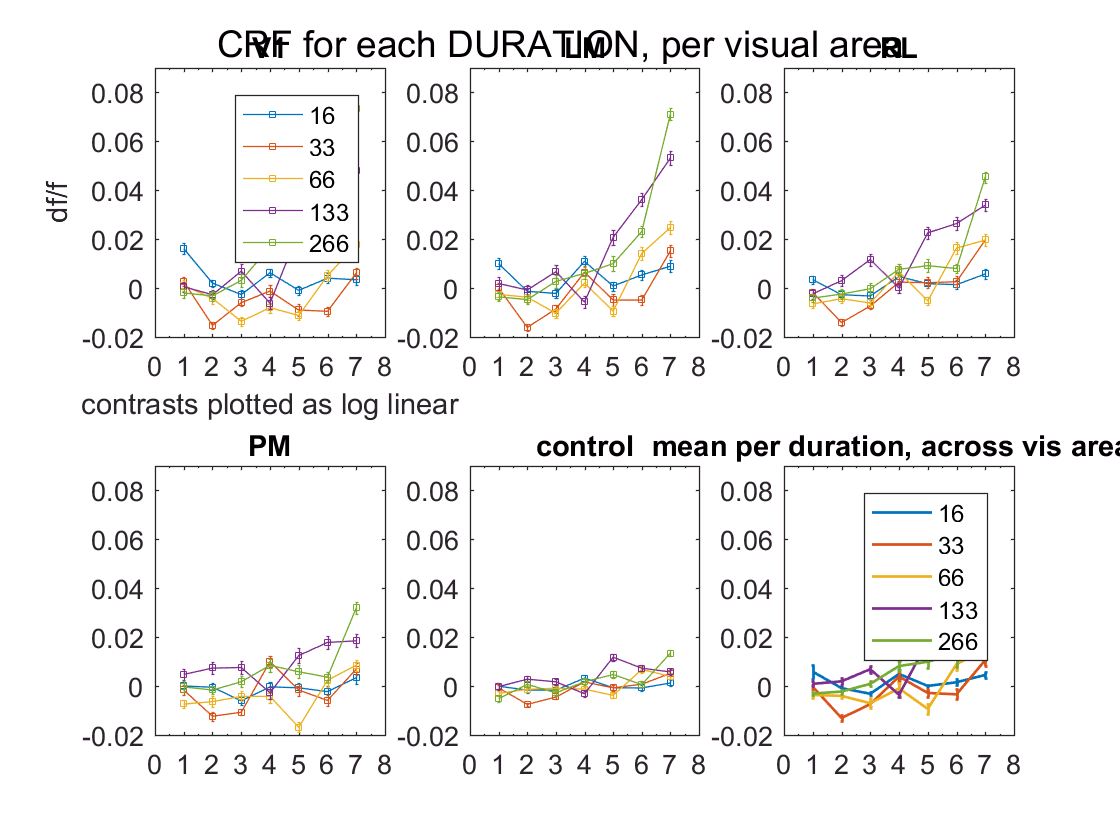

% figure first because all pts on one figure
figure 
suptitle('CRF for each DURATION, per visual area')

clear r 
r = 1;

clear subplotNum
subplotNum = 1;

for i = 1:length(xpts) % for each point

    % for each duration we're gonna collect df/f @ frame 15 for each contrast (the CRF for each duration)
    for d = 1:length(uniqueDurations)
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        
        % for each duration at each contrast:
        for c = 1:length(uniqueContrasts)
            
             clear cthDthTrials
             clear sq5FramesOverTrialsPTSdfof
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % for each POINT, for each DUR, get CRF at the dth dur,
             % plot on i-th subplot, hold on, plot CRF at next dth dur etc until last dur
             % then leave con loop & dur loop, back in i loop, go to next subplot & repeat
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns 3 (frames) by # trials
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
           
             % STDERR
             % I want the error over trials, not over frames
             % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
            cthDtdStdErr(1,c) = stdErr;
        
        end
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        % one figure, one subplot for each point, each subplot has multiple traces 
        % the CRF for each DURATION 
        % number of subplot based on 5 points
        subplot(2,3,i) % we'll be in the ith loop until were done w/the dth duration loop
       
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        clear myplot
        myplot = errorbar(x_axis,cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,cthDtdStdErr,'-s','MarkerSize',3); 
        clear st
        st = title(sprintf('%s', reigons{r}));
        ylim([-0.02 0.09]) 
        xlim([0, 8])
        
        ax=myplot.Parent;
        ax.XMinorTick = 'on'; % more tick marks
        set(ax, 'XTick', 0:1:8);
        
        hold on % plot on same subplot for next duration
        
    end % ending the duration loop, right before next 'i' value
    
     if subplotNum == 1
        xlabel('contrasts plotted as log linear')
        ylabel('df/f')
        legend(durs4Legend)
    end 
        
subplotNum = subplotNum+1;
r = r+1;
    
end
%% 

% want to plot CRF for each dur, averaged across visual areas
hold on

clear d
for d = 1:length(uniqueDurations)
    
    clear allPtsAtDthDurMeanSqPTSdfofCthDthTrials % clear of CRF each
    % time we change d, not i
    
    clear i
    for i = 1:length(xpts) % for each duration we're gonna average the 
    % CRF across all visual areas /points
    
    clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        
        % for each duration at every point, get CRF
        clear c
        for c = 1:length(uniqueContrasts)
            
             clear cthDthTrials
             clear sq5FramesOverTrialsPTSdfof
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % taking cthDth trials for 1 point, returns df/f for frames x trials
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
             % now I need the mean over trials to get one df/f value representing the
             % average fluorescence over 3 frames and over the c-th trials for the i-th point
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
             % now I want to collect each c-th CRF value for this point
             % creates 1 x 7 (contrasts)
             contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        end
        
        % now we have a CRF for 1 duration at 1 point
        % we're still in the points and duration loops
        
        % inside the points & duration loops, 
        % collect CRF
        % this will give us a matrix where rows are points and columns are CRF values for one duration
        allPtsAtDthDurMeanSqPTSdfofCthDthTrials(i,:) = contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
   end  % now end the points loop so you can collect allPtsAtDthDurMeanSqPTSdfofCthDthTrials for the next point
  % goes to next point & repeats until allPtsAtDthDurMeanSqPTSdfofCthDthTrials is 5x7
   
   % STDERR 
   % I want the error over *points*
   clear stdErr
   clear numeratorStdErr
    
   numeratorStdErr = std(allPtsAtDthDurMeanSqPTSdfofCthDthTrials,1);
   stdErr = numeratorStdErr./sqrt(length(xpts)); % length xpts not sum trials here
     
   % now take the mean over points & get us back to one trace again, CRF over all points for 1 duration
        
   % outside the points loop & inside the duration loop, 
   % before about to switch to next duration - 
   % take mean across points of all CRFs for this duration
   meanAllPtsAtDthDurMeanSqPTSdfofCthDthTrials = mean(allPtsAtDthDurMeanSqPTSdfofCthDthTrials,1);
 
   % now plot mean CRF for that duration - don't store & plot later
   subplot(2,3,6)
   clear x_axis
   x_axis = [1 2 3 4 5 6 7];
   clear myplot
   myplot = errorbar(x_axis,meanAllPtsAtDthDurMeanSqPTSdfofCthDthTrials,stdErr,'linewidth',1);
   
   clear sst
   sst = title('mean per duration, across vis areas');
   ylim([-0.02 0.09])
   xlim([0 8])
   
     
   clear ax
   ax=myplot.Parent;
   ax.XMinorTick = 'on'; % more tick marks
   set(ax, 'XTick', 0:1:8);
     
   hold on % because want next duration to plot here too

end % finally, go on to the next duration. When this section is complete you will
% have a subplot with a line for each CRF for each duration, averaged over points/visual areas

legend(durs4Legend)